# Shooting method for finding eigenvalues for Orr-Sommerfeld equation (6 Eqn)

clear; clc; close all;      % clears everything

### Defining Boundary conditions for Shooting method

xValues = [0 1];        % Domain length
y_St = 0;               % y at start
yD_St = 0;              % y' at start
yDD_St_Gs = 0;          % y'' at start (Guess value)
yDDD_St = 0.1;          % y''' at start
yi_St = 0;
yiD_St = 0;

### Solving

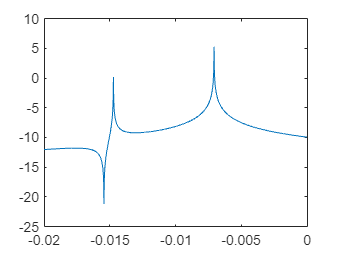

ci = -0.02:0.00001:0;
s = zeros(1,length(ci));
for l = 1:length(ci)
    tempFunc = @(abc) odeSolve(xValues, y_St, yD_St, abc, yDDD_St,yi_St,yiD_St,ci(l));
    yDD_St_Final = fzero(tempFunc, yDD_St_Gs);
    s(l) = odeSolve2(xValues, y_St, yD_St, yDD_St_Final, yDDD_St,yi_St,yiD_St,ci(l));
end

plot(ci,log(s));

### ODE Definition

function resi = odeSolve(XV, bc1, bc2, bc3, bc4, bc5, bc6, cComp)
    Re = 2500;
    Alp = 1;
    cr = 0.301148;
    Y = [bc1;bc2;bc3;bc4;bc5;bc6];
    [~,b] = ode45(@odedef, XV, Y);
    resi = b(end,1) + b(end,2);
    function dYdx = odedef(x,Y)
        y = Y(1);
        dydx = Y(2);
        d2ydx2 = Y(3);
        d3ydx3 = Y(4);
        yi = Y(5);
        dydxi = Y(6);
        dYdx(1,1) = dydx;
        dYdx(2,1) = d2ydx2;
        dYdx(3,1) = d3ydx3;
        dYdx(4,1) = (2*(Alp^2) + Re*Alp*cComp)*d2ydx2 - (Alp^4 + Re*(Alp^3)*cComp)*y;
        dYdx(5,1) = dydxi;
        const1 = Re*Alp*(2+Alp*(Alp*(1-x^2)-cr*Alp));
        const2 = Re*(Alp*(1-x^2)-cr*Alp);
        dYdx(6,1) = (const1/const2)*yi;
    end
end

function resi = odeSolve2(XV, bc1, bc2, bc3, bc4, bc5, bc6, cComp)
    Re = 2500;
    Alp = 1;
    cr = 0.301148;
    Y = [bc1;bc2;bc3;bc4;bc5;bc6];
    [~,b] = ode45(@odedef, XV, Y);
    resi = b(end,1)^2 + b(end,2)^2;
    function dYdx = odedef(x,Y)
        y = Y(1);
        dydx = Y(2);
        d2ydx2 = Y(3);
        d3ydx3 = Y(4);
        yi = Y(5);
        dydxi = Y(6);
        dYdx(1,1) = dydx;
        dYdx(2,1) = d2ydx2;
        dYdx(3,1) = d3ydx3;
        dYdx(4,1) = (2*(Alp^2) + Re*Alp*cComp)*d2ydx2 - (Alp^4 + Re*(Alp^3)*cComp)*y;
        dYdx(5,1) = dydxi;
        const1 = Re*Alp*(2+Alp*(Alp*(1-x^2)-cr));
        const2 = Re*(Alp*(1-x^2)-cr);
        dYdx(6,1) = (const1/const2)*yi;
    end
end